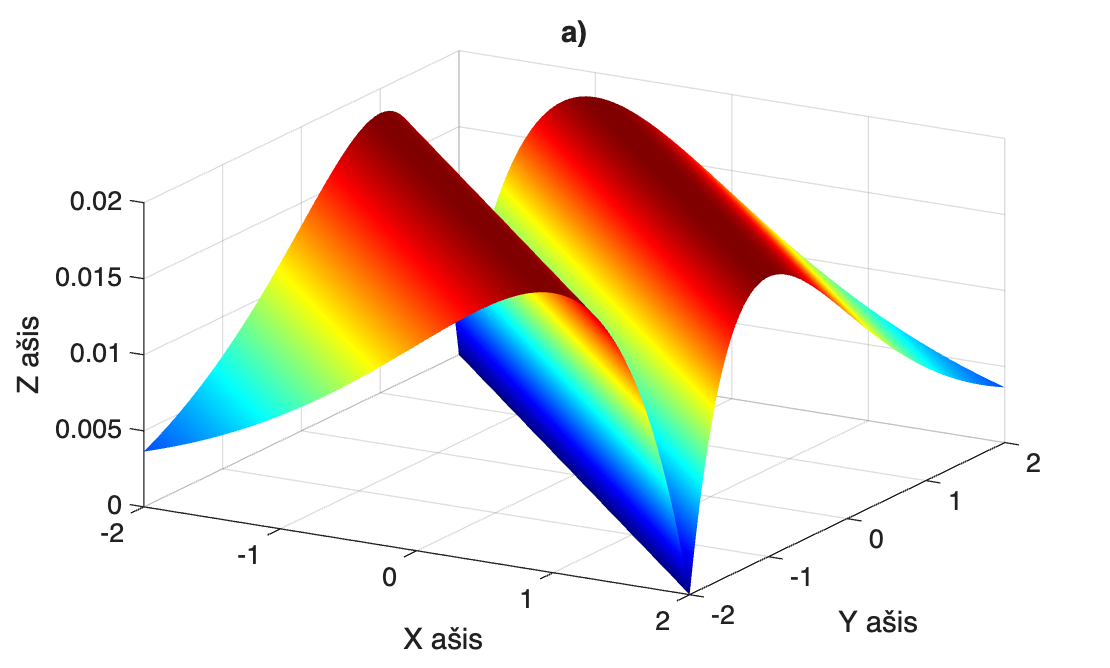

clear 
%a
x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);
[X, Y] = meshgrid(x, y);
Z = sin(abs(X + Y) / 20) .* exp(-abs(X + Y));
figure;

surf(X, Y, Z);
shading interp;
colormap('jet'); 

title('a)');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');
grid on;
view(30, 30);

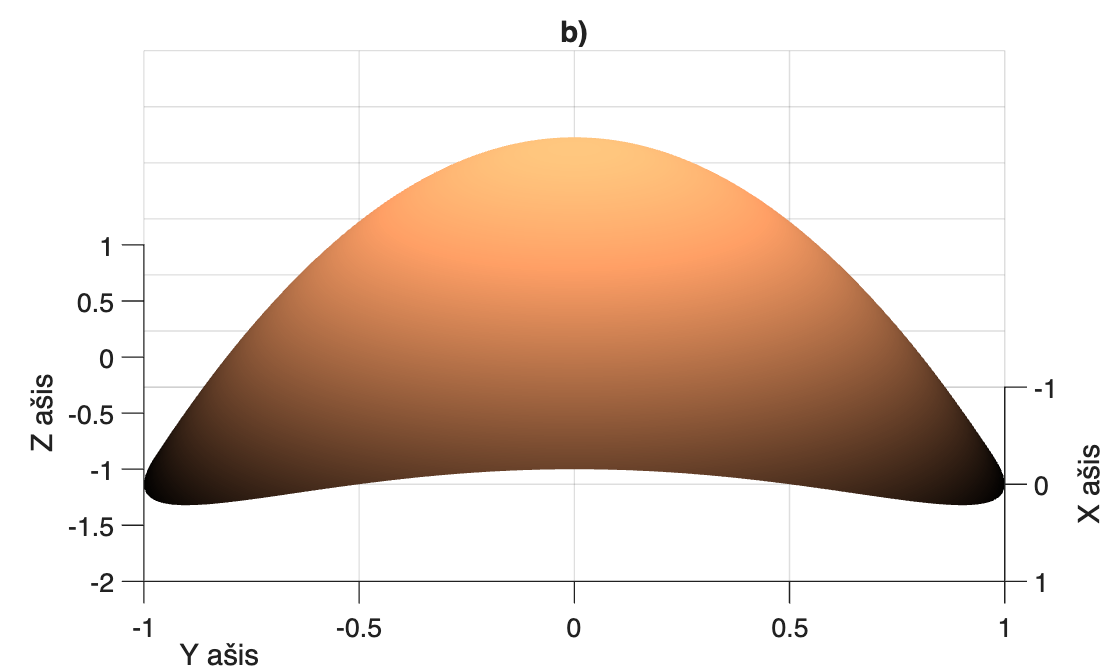


%b
r = linspace(0, 1, 50);
theta = linspace(0, 2*pi, 100);
[R, Theta] = meshgrid(r, theta);

X2 = R .* cos(Theta);
Y2 = R .* sin(Theta);

Z2 = 1 - 2*(X2.^2) - 3*(Y2.^2);

surf(X2, Y2, Z2);
shading interp;
colormap('copper');

title('b)');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');
grid on;
view(90, 30);

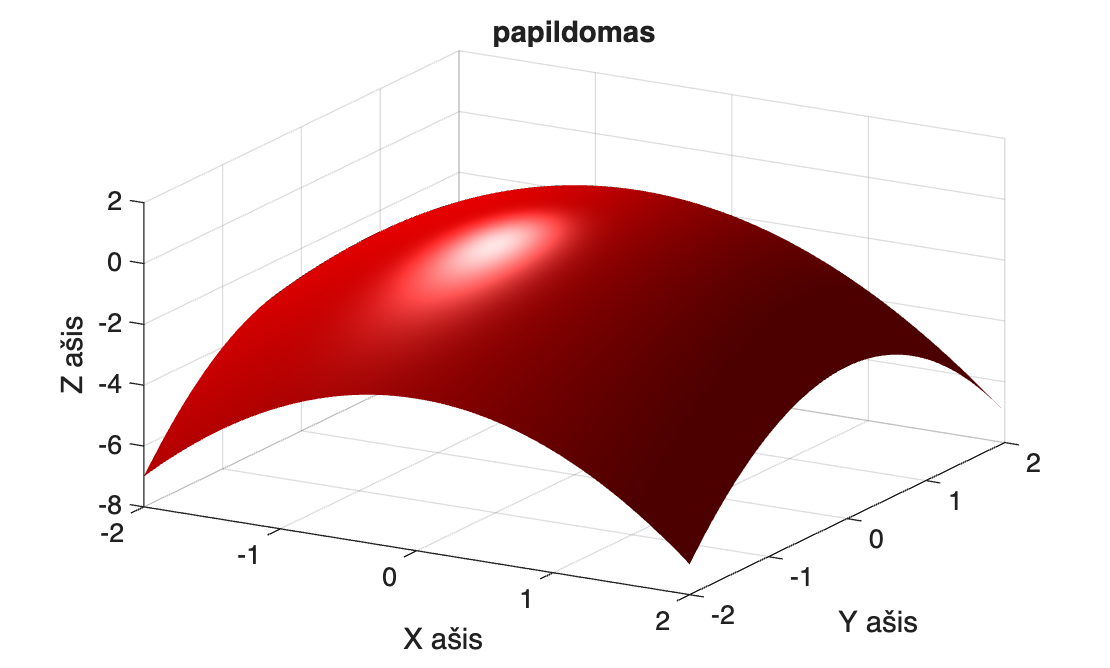


%papildomas
clear; clc; close all;

x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);
[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

figure;
surf(X, Y, Z);
shading interp;      
colormap([1 0 0]);   

camlight('left');    
lighting gouraud;    

title('papildomas');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');
grid on;
view(30, 30);      